clear all; clc; close all;

addpath('external');
addpath('..')

file_list = natsortfiles(dir('convergence/*mat'));
file_strc = 'splitter_conv_dab_lte_fo_correction_no_interp_dphase_%d.mat';

doa_samples_matrix = zeros(length(file_list),50);
corr_values_matrix = zeros(length(file_list),50);
num_samples_matrix = zeros(length(file_list),1);

for ii = 1:length(file_list)
    file_list(ii).name;
    load([file_list(ii).folder,filesep,file_list(ii).name]);

    doa_samples_matrix(ii,:) = abs(doa_samples_2)';
    corr_values_matrix(ii,:) = correlation_value(:,2)';
    num_samples_matrix(ii) = sscanf(file_list(ii).name,file_strc);
end

num_samples_matrix = [num_samples_matrix;1000000];
doa_samples_matrix = [doa_samples_matrix; zeros(1,50)];
corr_values_matrix = [corr_values_matrix; 0.512.*ones(1,50)];

doa_samples_mean = mean(doa_samples_matrix,2)/2;
% doa_samples_mean(doa_samples_mean > 250) = 250;
corr_values_mean = median(corr_values_matrix,2);

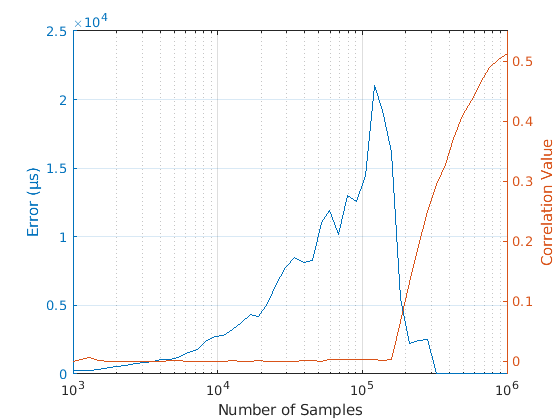

figure();
yyaxis left
semilogx(num_samples_matrix',doa_samples_mean');
xlabel('Number of Samples');
ylabel('Error (μs)'); 
yyaxis right
semilogx(num_samples_matrix',corr_values_mean);
ylabel('Correlation Value'); ylim([-0.021,0.55]);
hold on; grid on; 

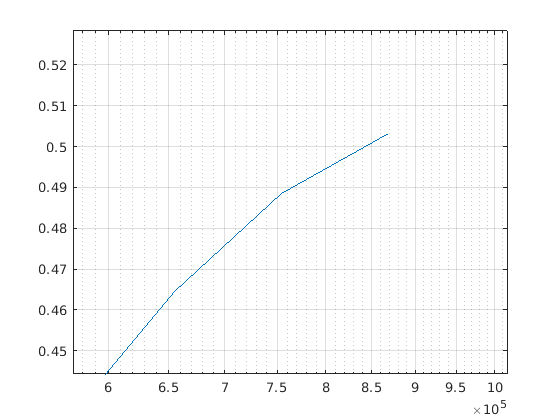

figure();
semilogx(num_samples_matrix',corr_values_mean);
hold on; grid on;